E-glass 21xK43 Gevetex :

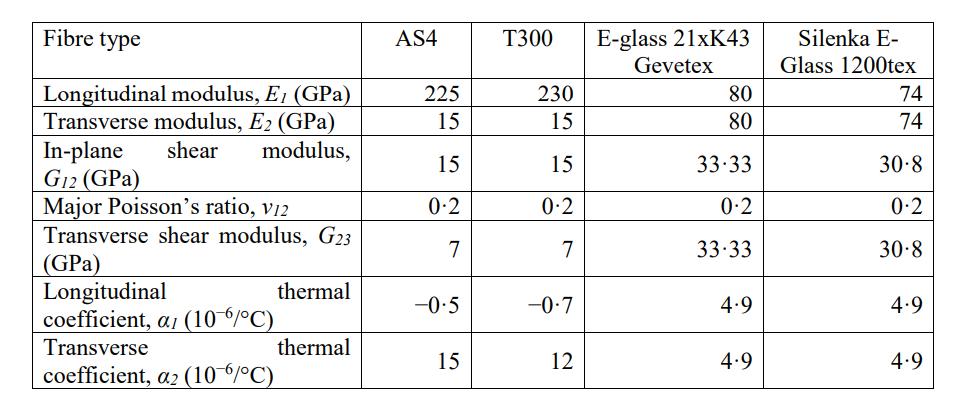

3501-6 epoxy

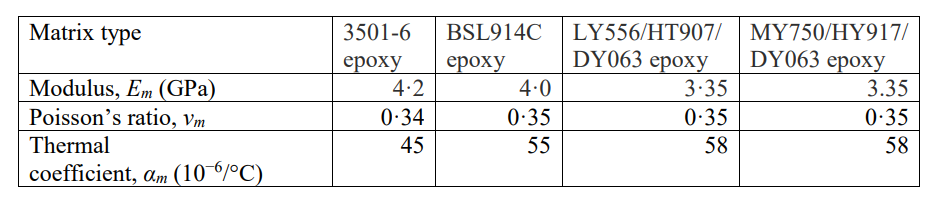

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

E_f = 80;
G_f = 33.33;
v_f = 0.2;
a_f = 4.9 * 1e-6;
K_f = E_f / (3 * (1 - 2 * v_f));

S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

E_m = 4.2;
v_m = 0.34;
a_m = 45 * 1e-6;
G_m = E_m/(2*(1+v_m));
K_m = E_m / (3 * (1 - 2 * v_m));

S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

%hills moduli
% fiber
syms n_f m_f k_f l_f p_f
eqn1 = n_f == C_f(1,1);
eqn2 = l_f == C_f(1,2);
eqn3 = k_f + m_f == C_f(2,2);
eqn4 = m_f == C_f(4,4);
eqn5 = p_f == C_f(5,5);

fiber = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_f,l_f,k_f,m_f,p_f]);
n_f = double(fiber.n_f);
m_f = double(fiber.m_f);
k_f = double(fiber.k_f);
l_f = double(fiber.l_f);
p_f = double(fiber.p_f);

% matrix
syms n_m m_m k_m l_m p_m
eqn1 = n_m == C_m(1,1);
eqn2 = l_m == C_m(1,2);
eqn3 = k_m + m_m == C_m(2,2);
eqn4 = m_m == C_m(4,4);
eqn5 = p_m == C_m(5,5);

matrix = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_m,l_m,k_m,m_m,p_m]);
n_m = double(matrix.n_m);
m_m = double(matrix.m_m);
k_m = double(matrix.k_m);
l_m = double(matrix.l_m);
p_m = double(matrix.p_m);

For plot :

E1 = zeros(9,length(Vf_val));
E2 = zeros(9,length(Vf_val));
v12 = zeros(9,length(Vf_val));
v23 = zeros(8,length(Vf_val));
G12 = zeros(9,length(Vf_val));
G23 = zeros(8,length(Vf_val));

# *Strength of materials approach :*

%axial youngs modulus
E1_c = E_f*Vf + E_m*(1-Vf);
E1_c = subs(E1_c,Vf_val);
E1(1,:) = E1_c;

%axial poisson's ratio
v12_c = v_f*Vf + v_m*(1-Vf);
v12_c = subs(v12_c,Vf_val);
v12(1,:) = v12_c;

%direction 2 youngs modulus
E2_c = E_f*E_m / (E_m*Vf + E_f*(1-Vf));
E2_c = subs(E2_c,Vf_val);
E2(1,:) = E2_c;

%axial shear modulus
G12_c = G_f*G_m / (G_m*Vf + G_f*(1-Vf));
G12_c = subs(G12_c,Vf_val);
G12(1,:) = G12_c;

% %thermal coeff in direction 1
% a1_c = ((a_f*E_f - a_m*E_m)*Vf + a_m*E_m) / ((E_f - E_m)*Vf + E_m);
% a1_c = subs(a1_c,Vf_val);
% 
% %thermal coeff in direction 2
% a2_c = a_f*Vf + a_m*(1-Vf) + ((E_f*v_m - E_m*v_f) / (E1_c)) * (a_m - a_f) * (1-Vf) * Vf;
% a2_c = subs(a2_c,Vf_val);

# *Hills approach :*

%voight approximaation
C_c_v = C_m.*(1-Vf) + C_f.*Vf;
S_c_v = inv(C_c_v);

%Reuss approximation
S_c_r = S_m*(1-Vf) + S_f*Vf;

%E1
E1_c_v = 1/S_c_v(1,1);
E1_c_v_val = subs(E1_c_v,Vf_val);
E1(2,:) = E1_c_v_val;
E1_c_r = 1/S_c_r(1,1);
E1_c_r_val = subs(E1_c_r,Vf_val);
E1(3,:) = E1_c_r_val;

%E2
E2_c_v = 1/S_c_v(2,2);
E2_c_v_val = subs(E2_c_v,Vf_val);
E2(2,:) = E2_c_v_val;
E2_c_r = 1/S_c_r(2,2);
E2_c_r_val = subs(E2_c_r,Vf_val);
E2(3,:) = E2_c_r_val;

%v12
v12_c_v = -S_c_v(1,2)*E1_c_v;
v12_c_v_val = subs(v12_c_v,Vf_val);
v12(2,:) = v12_c_v_val;
v12_c_r = -S_c_r(2,1)*E2_c_r;
v12_c_r_val = subs(v12_c_r,Vf_val);
v12(3,:) = v12_c_r_val;

%v23
v23_c_v = -S_c_v(2,3)*E2_c_v;
v23_c_v_val = subs(v23_c_v,Vf_val);
v23(1,:) = v23_c_v_val;
v23_c_r = -S_c_r(3,2)*E2_c_r;
v23_c_r_val = subs(v23_c_r,Vf_val);
v23(2,:) = v23_c_r_val;

%G12
G12_c_v = 1/S_c_v(5,5);
G12_c_v_val = subs(G12_c_v,Vf_val);
G12(2,:) = G12_c_v_val;
G12_c_r = 1/S_c_r(5,5);
G12_c_r_val = subs(G12_c_r,Vf_val);
G12(3,:) = G12_c_r_val;

%G23
G23_c_v = 1/S_c_v(4,4);
G23_c_v_val = subs(G23_c_v,Vf_val);
G23(1,:) = G23_c_v_val;
G23_c_r = 1/S_c_r(4,4);
G23_c_r_val = subs(G23_c_r,Vf_val);
G23(2,:) = G23_c_r_val;

# *CCA approach :*

% Predefine arrays for results
E1_c_val = zeros(size(Vf_val));
v12_c_val = zeros(size(Vf_val));
k23_c_val = zeros(size(Vf_val));
G12_c_val = zeros(size(Vf_val));
G23_c_val = zeros(size(Vf_val));
E2_c_val = zeros(size(Vf_val));
v23_c_val = zeros(size(Vf_val));
v21_c_val = zeros(size(Vf_val));

r = G_f / G_m;
eta_m = 3 - 4 * v_m;
eta_f = 3 - 4 * v_f;

for i = 1:length(Vf_val)
    Vf_i = Vf_val(i);

    % A and B for E1 and v12
    A_E = (1 - Vf_i) * G_m / (K_f + 0.5 * G_f);
    B_E = Vf_i * G_m / (K_m + G_m / 3);

    % E1*
    E1_cca = Vf_i * E_f + (1 - Vf_i) * E_m + ...
        (4 * Vf_i * (1 - Vf_i) * (v_f - v_m)^2 * G_m) / (A_E + B_E + 1);
    E1_c_val(i) = E1_cca;

    % v12*
    v12_cca = (1 - Vf_i) * v_m + Vf_i * v_f + ...
        (Vf_i * (1 - Vf_i) * (v_f - v_m) * ...
        (G_m / (K_m + G_m / 3) - G_m / (K_f + G_f / 3))) / (A_E + B_E + 1);
    v12_c_val(i) = v12_cca;

    % k23*
    k23_cca = K_m + G_m / 3 + Vf_i / ...
        (1 / ((K_f - K_m) + (G_f - G_m) / 3) + (1 - Vf_i) / (K_m + 4 * G_m / 3));
    k23_c_val(i) = k23_cca;

    % G12*
    G12_cca = G_m * ((G_f * (1 + Vf_i) + G_m * (1 - Vf_i)) / ...
        (G_f * (1 - Vf_i) + G_m * (1 + Vf_i)));
    G12_c_val(i) = G12_cca;

    % G23* from roots
    a = 3 * Vf_i * (1 - Vf_i)^2 * ((r - 1) * (r + eta_f));
    b = (r * eta_m + eta_f * eta_m - Vf_i^3 * (r * eta_m - eta_f)) * ...
        (eta_m * Vf_i * (r - 1) - (r * eta_m + 1));
    A_G23 = a + b;

    B_G23 = -6 * Vf_i * (1 - Vf_i)^2 * ((r - 1) * (r + eta_f)) + ...
        (r * eta_m + (r - 1) * Vf_i + 1) * ...
        ((eta_m - 1) * (r + eta_f) - 2 * Vf_i^3 * (r * eta_m - eta_f)) + ...
        Vf_i * (r - 1) * (eta_m + 1) * (r + eta_f + Vf_i^3 * (r * eta_m - eta_f));

    D_G23 = 3 * Vf_i * (1 - Vf_i)^2 * ((r - 1) * (r + eta_f)) + ...
        (r * eta_m + Vf_i * (r - 1) + 1) * ...
        (r + eta_f + Vf_i^3 * (r * eta_m - eta_f));

    % Solve for G23
    coeffs = [A_G23, B_G23, D_G23];
    roots_G23 = roots(coeffs);
    real_pos_roots = roots_G23(imag(roots_G23) == 0 & real(roots_G23) > 0);
    if ~isempty(real_pos_roots)
        G23_c_val(i) = real_pos_roots(1) * G_m;
    else
        G23_c_val(i) = NaN; % mark as undefined if no valid root
    end

    % E2*
    E2_cca = (4 * G23_c_val(i) * k23_cca) / ...
         (k23_cca + G23_c_val(i) + (4 * v12_cca^2 * G23_c_val(i) * k23_cca) / E1_cca);
    E2_c_val(i) = E2_cca;

    % v23*
    v23_cca = (k23_cca - G23_c_val(i) - (4 * v12_cca^2 * G23_c_val(i) * k23_cca) / E1_cca) / ...
          (k23_cca + G23_c_val(i) + (4 * v12_cca^2 * G23_c_val(i) * k23_cca) / E1_cca);
    v23_c_val(i) = v23_cca;

    % v21*
    v21_cca = (4 * v12_cca * G23_c_val(i) * k23_cca) / ...
          (E1_cca * (k23_cca + G23_c_val(i)) + 4 * v12_cca^2 * G23_c_val(i) * k23_cca);
    v21_c_val(i) = v21_cca;
end

E1(4,:) = E1_c_val;

v12(4,:) = v12_c_val;

G12(4,:) = G12_c_val;

G23(3,:) = G23_c_val;

E2(4,:) = E2_c_val;

v23(3,:) = v23_c_val;

# *Self consistent method :*

Vf_val = linspace(0, 1, 101);
Vm_val = 1 - Vf_val;

E_f = 80;
G_f = 33.33;
v_f = 0.2;

S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

E_m = 4.2;
v_m = 0.34;
G_m = E_m/(2*(1+v_m));

S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

% fiber
syms n_f m_f k_f l_f p_f
eqn1 = n_f == C_f(1,1);
eqn2 = l_f == C_f(1,2);
eqn3 = k_f + m_f == C_f(2,2);
eqn4 = m_f == C_f(4,4);
eqn5 = p_f == C_f(5,5);

fiber = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_f,l_f,k_f,m_f,p_f]);
n_f = double(fiber.n_f);
m_f = double(fiber.m_f);
k_f = double(fiber.k_f);
l_f = double(fiber.l_f);
p_f = double(fiber.p_f);

% matrix
syms n_m m_m k_m l_m p_m
eqn1 = n_m == C_m(1,1);
eqn2 = l_m == C_m(1,2);
eqn3 = k_m + m_m == C_m(2,2);
eqn4 = m_m == C_m(4,4);
eqn5 = p_m == C_m(5,5);

matrix = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_m,l_m,k_m,m_m,p_m]);
n_m = double(matrix.n_m);
m_m = double(matrix.m_m);
k_m = double(matrix.k_m);
l_m = double(matrix.l_m);
p_m = double(matrix.p_m);

% Storage for results
k_c_c = zeros(size(Vf_val));
m_c_c = zeros(size(Vf_val));
p_c_c = zeros(size(Vf_val));


k_c_c(1) = k_m;
m_c_c(1) = l_m;
p_c_c(1) = p_m;

k_c_c(length(Vf_val)) = k_f;
m_c_c(length(Vf_val)) = l_f;
p_c_c(length(Vf_val)) = p_f;

for i = 2:length(Vf_val)-1
    current_Vf = Vf_val(i);
    current_Vm = Vm_val(i);

    syms k_star m_star p_star
    
    eq1 = (current_Vf * k_f) / (k_f + m_star) + (current_Vm * k_m) / (k_m + m_star) == ...
          2 * ((current_Vf * m_m) / (m_m - m_star) + (current_Vm * m_f) / (m_f - m_star));
    
    eq2 = (1 / (2 * p_star)) == (current_Vf / (2 * (p_star - p_m))) + (current_Vm / (2 * (p_star - p_f)));
    
    eq3 = (1 / (k_star + m_star)) == (current_Vf / (k_f + m_star)) + (current_Vm / (k_m + m_star));

    sol = solve([eq1, eq2, eq3], [k_star, m_star, p_star]);
    
    k_star_sol = double(sol.k_star);
    m_star_sol = double(sol.m_star);
    p_star_sol = double(sol.p_star);
    
    valid_idx = find(isreal(k_star_sol) & isreal(m_star_sol) & isreal(p_star_sol) & ...
                     (k_star_sol >= 0) & (m_star_sol >= 0) & (p_star_sol >= 0));

    k_c_c(i) = k_star_sol(valid_idx(1));
    m_c_c(i) = m_star_sol(valid_idx(1));
    p_c_c(i) = p_star_sol(valid_idx(1));
end

l_c_c = zeros(size(Vf_val));
n_c_c = zeros(size(Vf_val));

l_c_c(1) = l_m;
l_c_c(end) = l_f;

n_c_c(1) = n_m;
n_c_c(end) = n_f;

for i = 2:length(Vf_val)-1
    current_Vf = Vf_val(i);
    current_Vm = Vm_val(i);

    k_star = k_c_c(i);
    m_star = m_c_c(i);

    A = (k_f - k_m) / (l_f - l_m);

    l_star = l_f + (k_star - k_f)/A;

    n_star = (l_star - current_Vf * l_f - current_Vm * l_m)/A + ...
             current_Vf * n_f + current_Vm * n_m;

    l_c_c(i) = l_star;
    n_c_c(i) = n_star;
end

C_c_all = cell(size(Vf_val));
S_c_all = cell(size(Vf_val));

for i = 1:length(Vf_val)

    C_c = [n_c_c(i), l_c_c(i), l_c_c(i), 0,      0,      0;
           l_c_c(i), k_c_c(i)+m_c_c(i), k_c_c(i)-m_c_c(i), 0, 0, 0;
           l_c_c(i), k_c_c(i)-m_c_c(i), k_c_c(i)+m_c_c(i), 0, 0, 0;
           0,      0,      0,      m_c_c(i), 0,      0;
           0,      0,      0,      0,      p_c_c(i), 0;
           0,      0,      0,      0,      0,      p_c_c(i)];

    S_c = inv(C_c);

    C_c_all{i} = C_c;
    S_c_all{i} = S_c;
end

E1_c_c_val   = zeros(size(Vf_val));
E2_c_c_val   = zeros(size(Vf_val));
v12_c_c_val  = zeros(size(Vf_val));
v23_c_c_val  = zeros(size(Vf_val));
G12_c_c_val  = zeros(size(Vf_val));
G23_c_c_val  = zeros(size(Vf_val));

E1_c_c_val(1)  = E_m; 
E2_c_c_val(1)  = E_m; 
v12_c_c_val(1) = v_m;
v23_c_c_val(1) = v_m;
G12_c_c_val(1) = G_m;
G23_c_c_val(1) = G_m; 

E1_c_c_val(length(Vf_val))  = E_f; 
E2_c_c_val(length(Vf_val))  = E_f; 
v12_c_c_val(length(Vf_val)) = v_f;
v23_c_c_val(length(Vf_val)) = v_f;
G12_c_c_val(length(Vf_val)) = G_f;
G23_c_c_val(length(Vf_val)) = G_f; 

for i = 2:length(Vf_val)-1
    S = S_c_all{i};

    E1_c_c_val(i)  = 1 / S(1,1);
    E2_c_c_val(i)  = 1 / S(2,2);
    v12_c_c_val(i) = -S(1,2) * E1_c_c_val(i);
    v23_c_c_val(i) = -S(2,3) * E2_c_c_val(i);
    G12_c_c_val(i) = 1 / S(5,5);
    G23_c_c_val(i) = 1 / S(4,4);
end
E1(5,:) = E1_c_c_val;
E2(5,:) = E2_c_c_val;
v12(5,:) = v12_c_c_val;
v23(4,:) = v23_c_c_val;
G12(5,:) = G12_c_c_val;
G23(4,:) = G23_c_c_val;

# *Mori Tanaka approach :*

% composite 
k_c = (Vf*k_f*(k_m + m_m) + (1-Vf)*k_m*(k_f + m_m))/(Vf*(k_m + m_m) + (1-Vf)*(k_f + m_m));
l_c = (Vf*l_f*(k_m + m_m) + (1-Vf)*l_m*(k_f + m_m))/(Vf*(k_m + m_m) + (1-Vf)*(k_f + m_m));
n_c = (1-Vf)*n_m + Vf*n_f + (1-Vf)*Vf*(l_f-l_m)^2/(Vf*(k_m + m_m) + (1-Vf)*(k_f + m_m));
m_c = (m_f*m_m*(k_m+2*m_m)+Vf*m_f*k_m*m_m+(1-Vf)*m_m^2*k_m)/(k_m*m_m+(k_m+2*m_m)*(Vf*m_m+(1-Vf)*m_f));
p_c = p_m*(p_f*(1+Vf) + p_m*(1-Vf))/(p_f*(1-Vf) + p_m*(1+Vf));

C_c = [n_c, l_c, l_c, 0, 0, 0;
       l_c, k_c+m_c, k_c-m_c, 0, 0, 0;
       l_c, k_c-m_c, k_c+m_c, 0, 0, 0;
       0, 0, 0, m_c, 0, 0;
       0, 0, 0, 0, p_c, 0;
       0, 0, 0, 0, 0, p_c;];

S_c = inv(C_c);

%E1
E1_c = 1/S_c(1,1);
E1_c_val = subs(E1_c,Vf_val);
E1(6,:) = E1_c_val;

%E2
E2_c = 1/S_c(2,2);
E2_c_val = subs(E2_c,Vf_val);
E2(6,:) = E2_c_val;

%v12
v12_c = -S_c(1,2)*E1_c;
v12_c_val = subs(v12_c,Vf_val);
v12(6,:) = v12_c_val;

%v23
v23_c = -S_c(2,3)*E2_c;
v23_c_val = subs(v23_c,Vf_val);
v23(5,:) = v23_c_val;

%G12
G12_c = 1/S_c(5,5);
G12_c_val = subs(G12_c,Vf_val);
G12(6,:) = G12_c_val;

%G23
G23_c = 1/S_c(4,4);
G23_c_val = subs(G23_c,Vf_val);
G23(5,:) = G23_c_val;

# *Tsai approach :*

zeta = 2;

eta_1 = ((k_f/k_m) - 1) / ((k_f/k_m) + zeta);
k_c = k_m * ((1 + zeta * eta_1 * Vf) / (1 - eta_1 * Vf));

eta_2 = ((l_f/l_m) - 1) / ((l_f/l_m) + zeta);
l_c = l_m * ((1 + zeta * eta_2 * Vf) / (1 - eta_2 * Vf));

eta_3 = ((m_f/m_m) - 1) / ((m_f/m_m) + zeta);
m_c = m_m * ((1 + zeta * eta_3 * Vf) / (1 - eta_3 * Vf));

eta_4 = ((n_f/n_m) - 1) / ((n_f/n_m) + zeta);
n_c = n_m * ((1 + zeta * eta_4 * Vf) / (1 - eta_4 * Vf));

eta_5 = ((p_f/p_m) - 1) / ((p_f/p_m) + zeta);
p_c = p_m * ((1 + zeta * eta_5 * Vf) / (1 - eta_5 * Vf));

C_c = [n_c, l_c, l_c, 0, 0, 0;
       l_c, k_c+m_c, k_c-m_c, 0, 0, 0;
       l_c, k_c-m_c, k_c+m_c, 0, 0, 0;
       0, 0, 0, m_c, 0, 0;
       0, 0, 0, 0, p_c, 0;
       0, 0, 0, 0, 0, p_c;];

S_c = inv(C_c);

%E1
E1_c = Vf * E_f + (1 - Vf) * E_m;
E1_c_val = subs(E1_c,Vf_val);
E1(7,:) = E1_c_val;

%E2
E2_c = 1/S_c(2,2);
E2_c_val = subs(E2_c,Vf_val);
E2(7,:) = E2_c_val;

%v12
v12_c = Vf * v_f + (1 - Vf) * v_m;
v12_c_val = subs(v12_c,Vf_val);
v12(7,:) = v12_c_val;

%v23
v23_c = -S_c(3,2)*E2_c;
v23_c_val = subs(v23_c,Vf_val);
v23(6,:) = v23_c_val;

%G12
G12_c = 1/S_c(5,5);
G12_c_val = subs(G12_c,Vf_val);
G12(7,:) = G12_c_val;

%G23
G23_c = 1/S_c(4,4);
G23_c_val = subs(G23_c,Vf_val);
G23(6,:) = G23_c_val;

# *Strikemen approach :*

%E1
E1_minus = (E_m * (1-Vf)) + (E_f * Vf) + ((4 * ((v_f - v_m)^2) * Vf * (1-Vf)) /(((1-Vf) / k_f) + (Vf / k_m) + (1 / G_m)));
E1_minus = subs(E1_minus,Vf_val);
E1(8,:) = E1_minus;
E1_plus = (E_m * (1-Vf)) + (E_f * Vf) + ((4 * ((v_f - v_m)^2) * Vf * (1-Vf)) /(((1-Vf) / k_f) + (Vf / k_m) + (1 / G_f)));
E1_plus = subs(E1_plus,Vf_val);
E1(9,:) = E1_plus;

%v12
v12_minus = v_m * (1-Vf) + v_f * Vf + ( (v_m - v_f) * (1 / k_f - 1 / k_m) * Vf * (1-Vf)) / ((1-Vf) / k_f + Vf / k_m + 1 / G_f);
v12_minus = subs(v12_minus,Vf_val);
v12(8,:) = v12_minus;
v12_plus = v_m * (1-Vf) + v_f * Vf + ( (v_f - v_m) * (1 / k_m - 1 / k_f) * Vf * (1-Vf)) / ((1-Vf) / k_f + Vf / k_m + 1 / G_m);
v12_plus = subs(v12_plus,Vf_val);
v12(9,:) = v12_plus;

%G12
G12_minus = G_m * ((G_m * (1-Vf) + G_f * (1 + Vf)) / (G_f * (1-Vf) + G_m * (1 + Vf)));
G12_minus = subs(G12_minus,Vf_val);
G12(8,:) = G12_minus;
G12_plus = G_f * ((G_f * Vf + G_m * (1 + (1-Vf))) / (G_m * Vf + G_f * (1 + (1-Vf))));
G12_plus = subs(G12_plus,Vf_val);
G12(9,:) = G12_plus;

%constant
gamma = G_f / G_m;
beta1 = k_f / (k_f + (2 * G_m));
beta2 = k_f / (k_f + (2 * G_f));
alpha = (beta1 - gamma * beta2) / (1 + gamma * beta2);
rho = (gamma + beta1) / (gamma - 1);

%G23
G23_minus = G_m + (Vf / (1 / (G_f - G_m) + ((k_m + 2 * G_m) * (1-Vf)) / (2 * G_m * (k_m + G_m))));
G23_minus = subs(G23_minus,Vf_val);
G23(7,:) = G23_minus;
G23_plus = G_m * ( 1 + (((1 + beta1) * Vf) / (rho - (Vf * (1 + ((3 * beta1^2 * (1-Vf)^2) / (alpha * (Vf^3) + 1)))))));
G23_plus = subs(G23_plus,Vf_val);
G23(8,:) = G23_plus;

%K
K_minus = k_m + (Vf / (1 / (k_f - k_m) + ((1-Vf) / (k_m + G_m))));
K_minus = subs(K_minus,Vf_val);
K_plus = k_f + ((1-Vf) / (1 / (k_m - k_f) + (Vf / (k_f + G_f))));
K_plus = subs(K_plus,Vf_val);

%E2
E2_minus = (4 * G23_minus .* K_minus) ./ (K_minus + G23_minus + ((4 * G23_minus .* K_minus .* (v12_plus).^2) ./ E1_minus));
E2(8,:) = E2_minus;
E2_plus = (4 * G23_plus .* K_plus) ./ (K_plus + G23_plus + ((4 * G23_plus .* K_plus .* (v12_minus).^2) ./ E1_plus));
E2(9,:) = E2_plus;

%v23
v23_minus = (K_minus - G23_plus - (4 * G23_plus .* K_minus .* (v12_plus).^2) ./ E1_minus) ./ (K_minus + G23_plus + (4 * G23_plus .* K_minus .* (v12_plus).^2) ./ E1_minus);
v23(7,:) = v23_minus;
v23_plus = (K_plus - G23_minus - (4 * G23_minus .* K_plus .* (v12_minus).^2) ./ E1_plus) ./ (K_plus + G23_minus + (4 * G23_minus .* K_plus .* (v12_minus).^2) ./ E1_plus);
v23(8,:) = v23_plus;

Plotting :

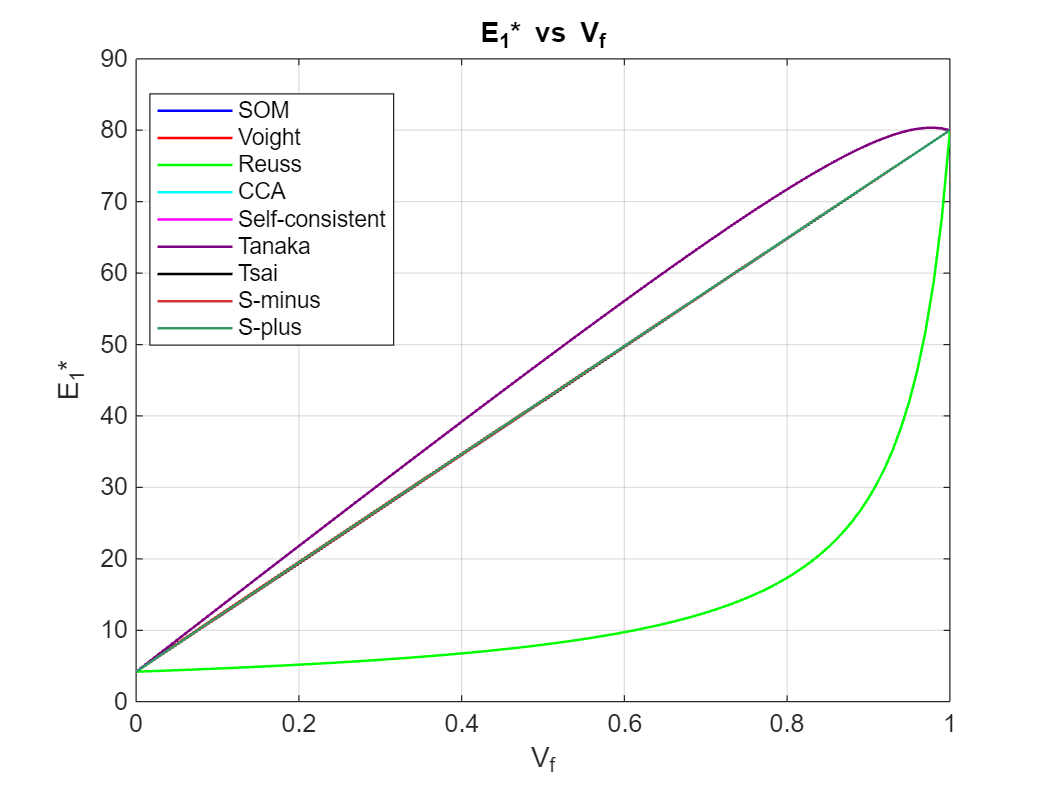

colorSet = {'b', 'r', 'g', 'c', 'm', [0.5 0 0.5], 'k', [0.8 0.2 0.2], [0.2 0.6 0.4]};

for i = 1:9
    plot(Vf_val, E1(i,:), 'LineWidth', 1, 'Color', colorSet{i});
    hold on;
end
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
grid on;
legend('SOM','Voight','Reuss','CCA','Self-consistent','Tanaka','Tsai','S-minus','S-plus', 'Location', 'best');

hold off

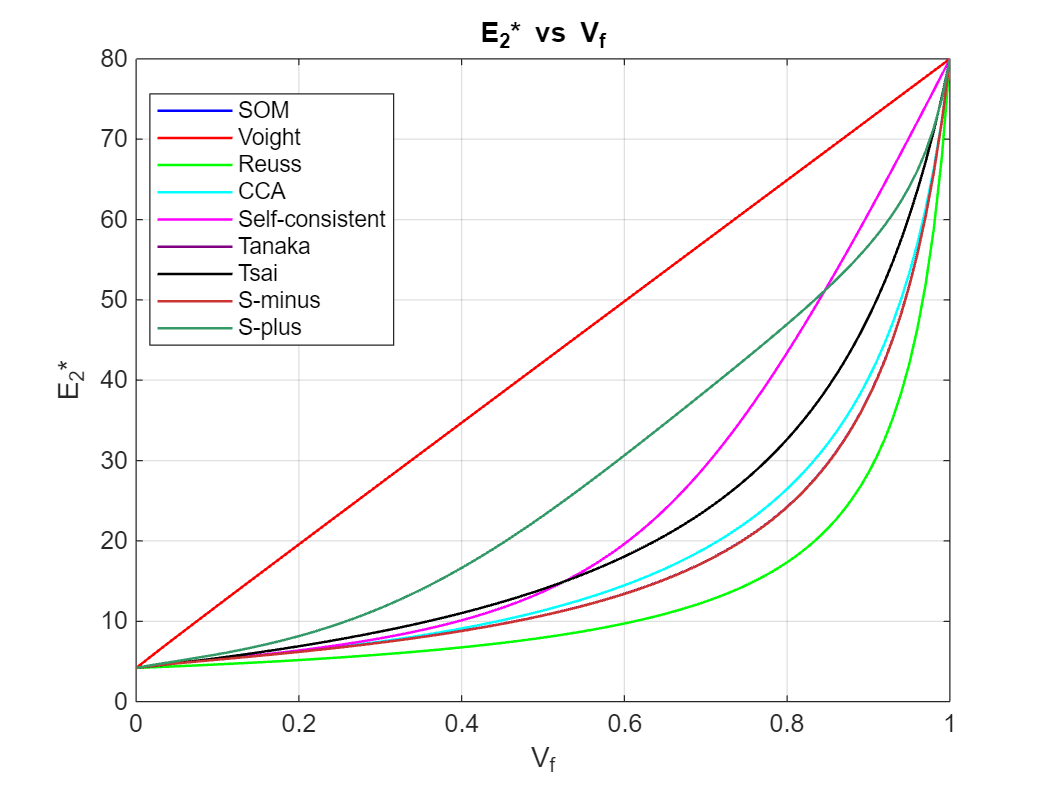

for i = 1:9
    plot(Vf_val, E2(i,:), 'LineWidth', 1, 'Color', colorSet{i});
    hold on;
end
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
grid on;
legend('SOM','Voight','Reuss','CCA','Self-consistent','Tanaka','Tsai','S-minus','S-plus', 'Location', 'best');

hold off;

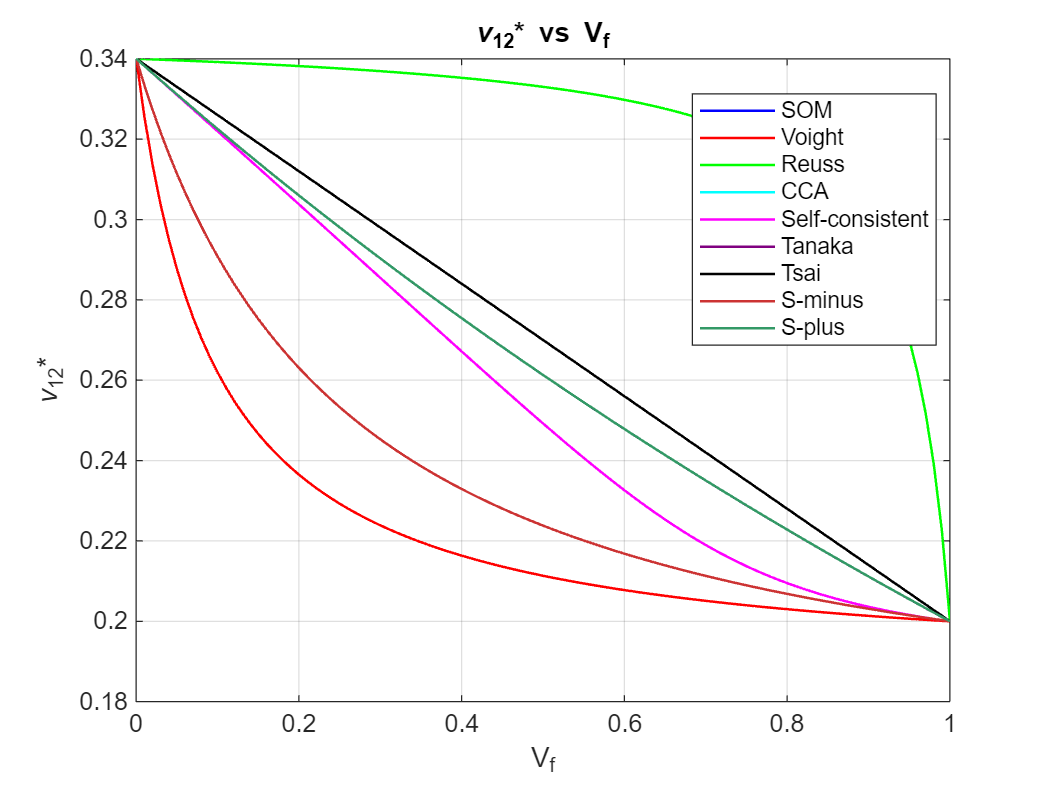


for i = 1:9
    plot(Vf_val, v12(i,:), 'LineWidth', 1, 'Color', colorSet{i});
    hold on;
end
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
grid on;
legend('SOM','Voight','Reuss','CCA','Self-consistent','Tanaka','Tsai','S-minus','S-plus', 'Location', 'best');

hold off;

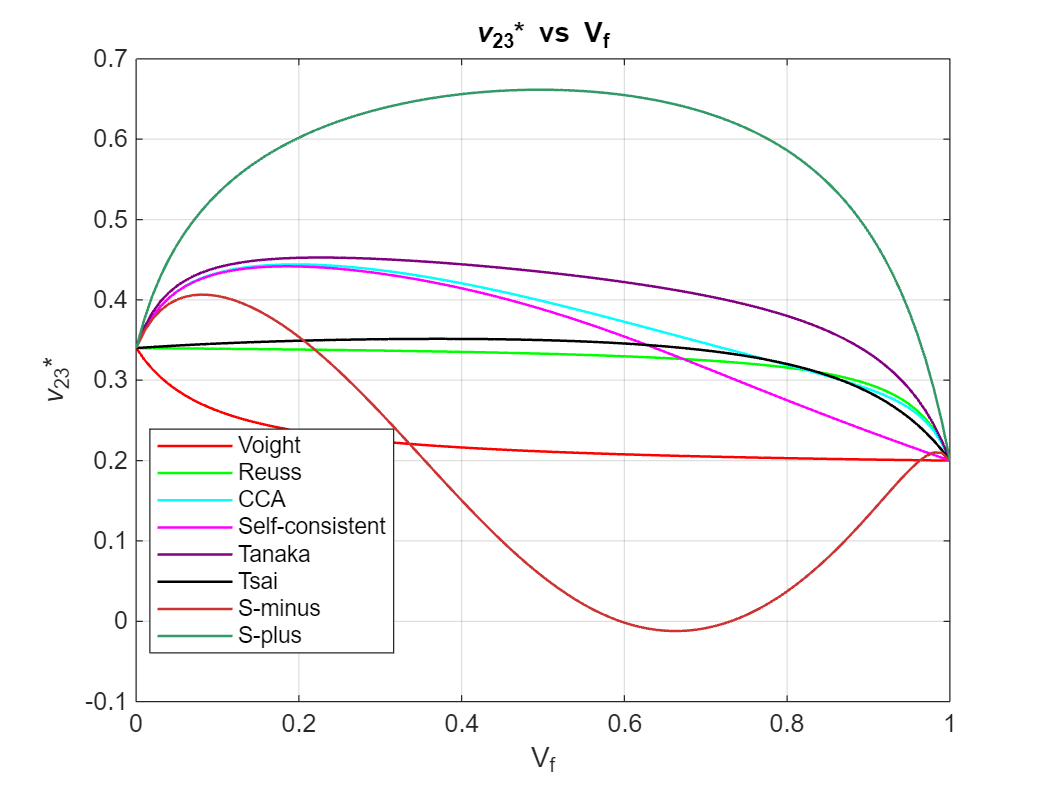


for i = 1:8
    plot(Vf_val, v23(i,:), 'LineWidth', 1, 'Color', colorSet{i+1});
    hold on;
end
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
grid on;
legend('Voight','Reuss','CCA','Self-consistent','Tanaka','Tsai','S-minus','S-plus', 'Location', 'best');

hold off;

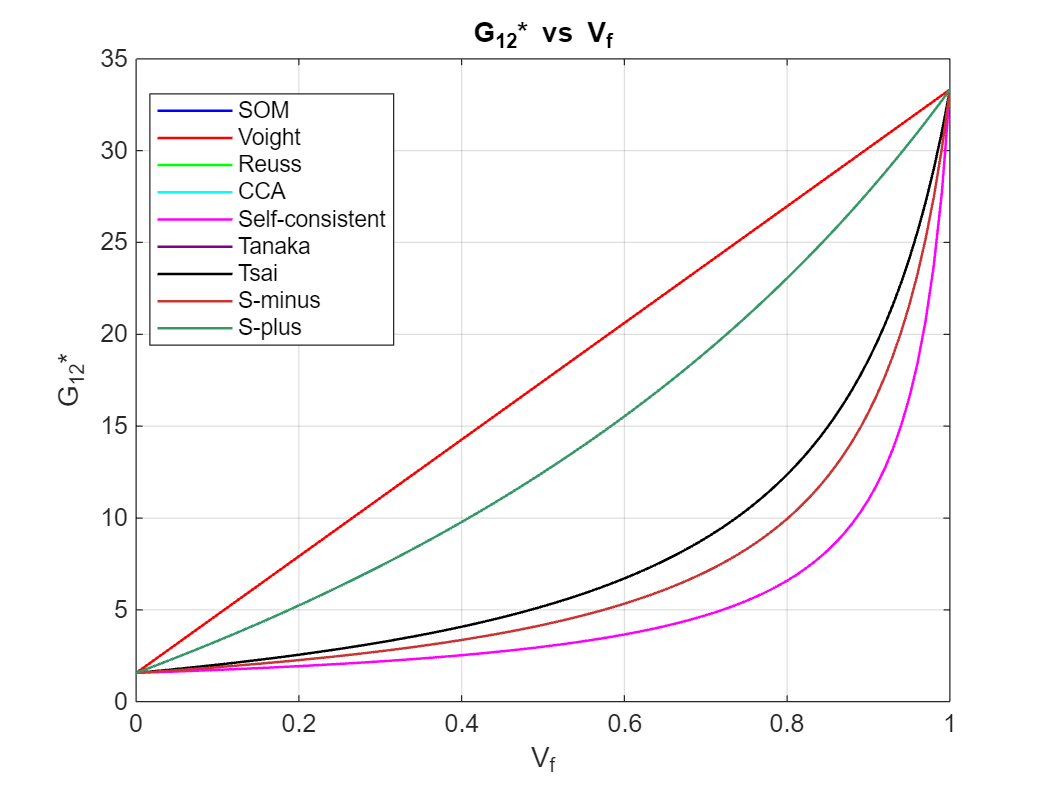


for i = 1:9
    plot(Vf_val, G12(i,:), 'LineWidth', 1, 'Color', colorSet{i});
    hold on;
end
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
grid on;
legend('SOM','Voight','Reuss','CCA','Self-consistent','Tanaka','Tsai','S-minus','S-plus', 'Location', 'best');

hold off;

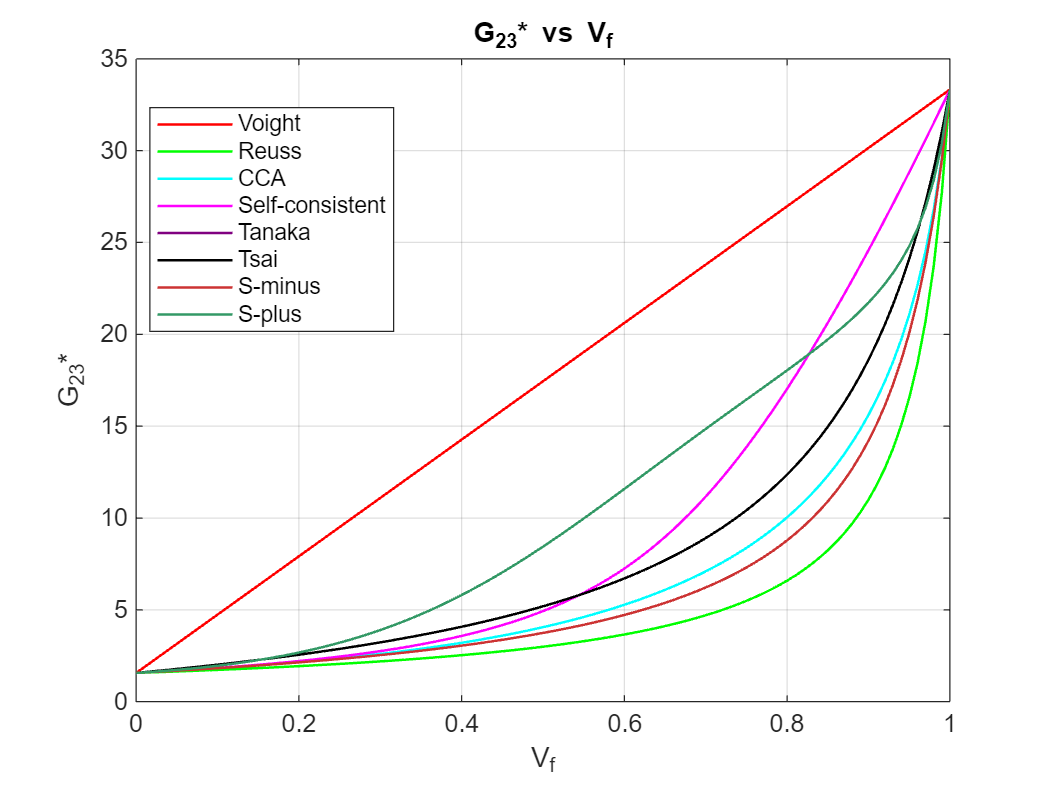


for i = 1:8
    plot(Vf_val, G23(i,:), 'LineWidth', 1, 'Color', colorSet{i+1});
    hold on;
end
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
grid on;
legend('Voight','Reuss','CCA','Self-consistent','Tanaka','Tsai','S-minus','S-plus', 'Location', 'best');